
%% Define simulation parameters
rng('default'); rng(0) % set the random number generator's starting value
g=9.81;        % gravity acceleration constant
qc=1;          % power spectral density of white noise excitation
r=0.1;         % measurement noise variance
x0=[1.5;0];    % initial state (radian angle and angular velocity)
DT=0.01;       % time step size
nk=500;        % number of steps

%% Generate the track and the measurements
T=(1:nk)*DT;   % timestamps
X=zeros(1,nk); % preallocate
Y=NaN(1,nk);   % preallocate using not-a-number
x=x0;
m=5;           % number of time steps per measurement
for k=1:nk 
    
    x1_hat = x(1) + DT/2*x(2);
    x(2) = x(2)-g*DT*sin(x1_hat) + sqrt(qc*DT)*randn;
    x(1) = x1_hat + DT/2*x(2);
   
    %for every 5th timestep we take measurement with noise
    if ~rem(k,1)
        Y(k)=sin(x(1))+sqrt(r)*randn;
    end
    X(k)=x(1);
end

%% Define some common filter parameters
m0 = [1.6;0];       % slightly off from x0
P0 = 0.1*eye(2);
Q=qc*[1/4*DT^3 1/2*DT^2;1/2*DT^2 DT];
R=r;



%% Run the filters and smoothers
filtername={'EKF','EKF2'};
GA={@GaussApproxEKF,@GaussApproxEKF2};
nf=length(filtername);
M1f=zeros(nf,nk);     M1s = zeros(nf,nk);
Mf=zeros(2,nk); Pf=zeros(2,2,nk);   % save for the smoother


RMS error for EKF is 0.14817
RMS error for EKF2 is 0.16742


for jf=1:nf
    m=m0; P=P0;
    for k=1:nk   % forward sweep (filter)
        [m,P]=gf_predict(m,P,@pendulum_f_leapfrog,Q,GA{jf});
        [m,P]=gf_update(m,P,Y(k),@pendulum_h,R,GA{jf});
        M1f(jf,k)=m(1);
        Mf(:,k)=m; Pf(:,:,k)=P;
    end
    rmse=sqrt(mean((X(1,:)-M1f(jf,:)).^2));
    disp(['RMS error for filter ' num2str(jf) ' is ' num2str(rmse)])
    
end

RMS error for filter 1 is 0.14817
RMS error for filter 2 is 0.16742


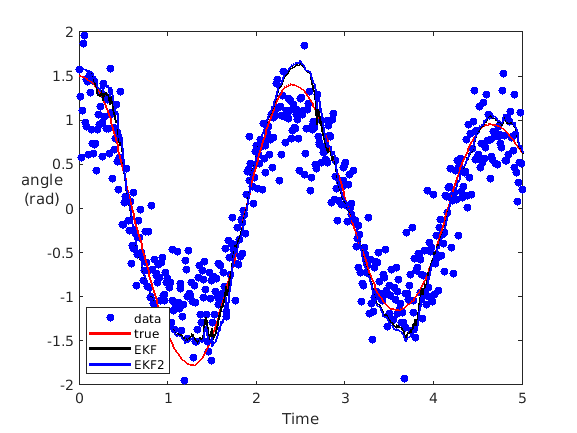

% EKF RMSE 0.14817
% EKF2 RMSE 0.16742


%% Plot the results
figure(1)
plot(T,Y,'b.', ...
    [0,T],[x0(1),X(1,:)],'r-',...
    [0,T],[m0(1),M1f(1,:)],'k-',...
    [0,T],[m0(1),M1f(2,:)],'b-','linewidth',2,'markersize',20);
xlabel('Time')
ylabel({'angle';'(rad)'},'rot',0)
legend('data','true',filtername{1},filtername{2},'location','SW')

Task4

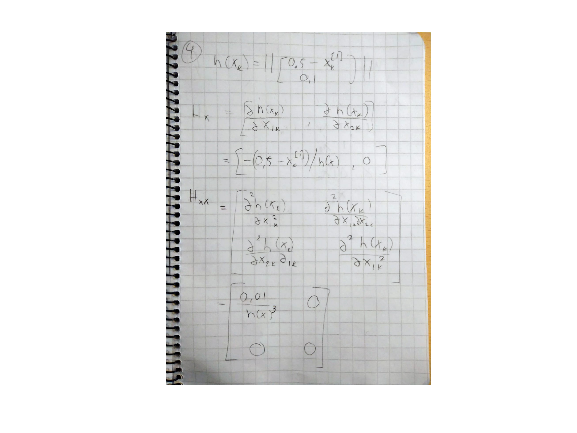

imshow(imread('Task4_solution.jpeg'))

Task 5

rng = 0
RMS error for filter 1 is 0.15054
RMS error for filter 2 is 0.15052


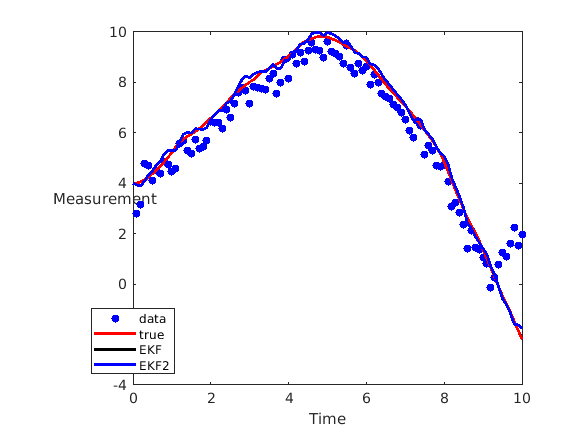

clear all;
task5(0)

Task 6

rng = 12
RMS error for filter 1 is 16.9177
RMS error for filter 2 is 0.17178


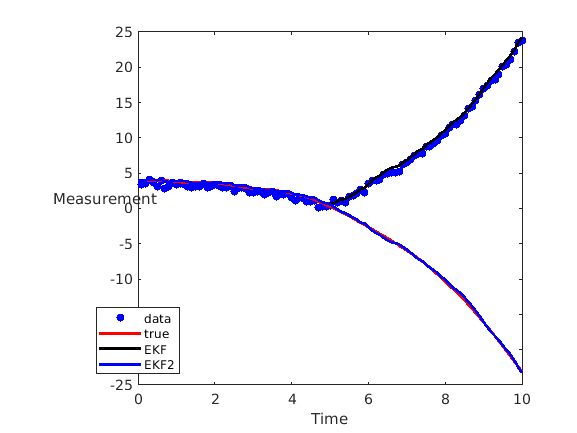

% rng 12
task5(12)

rng = 23
RMS error for filter 1 is 13.0778
RMS error for filter 2 is 13.0775


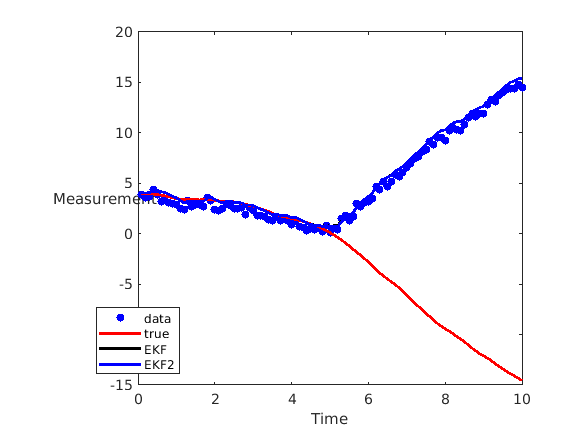

% EKF diverges

%rng 23
task5(23)

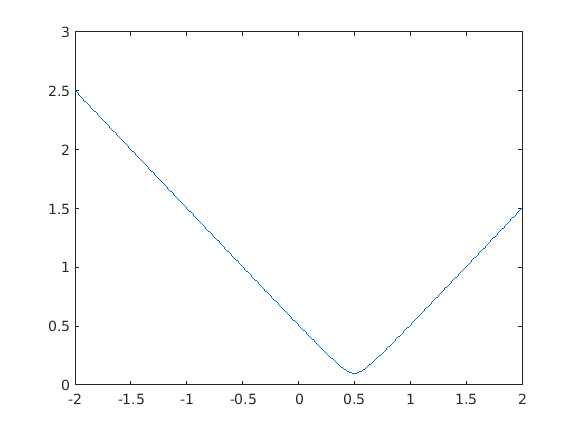

% both diverges

%Divergence happens when measurement approaches zero and it depends
% on rng whether EKF/EKF2 diverges or not.

%lets plot function h
x = -2:0.01:2;
figure
plot(x,sqrt((0.5-x).^2+0.1.^2))

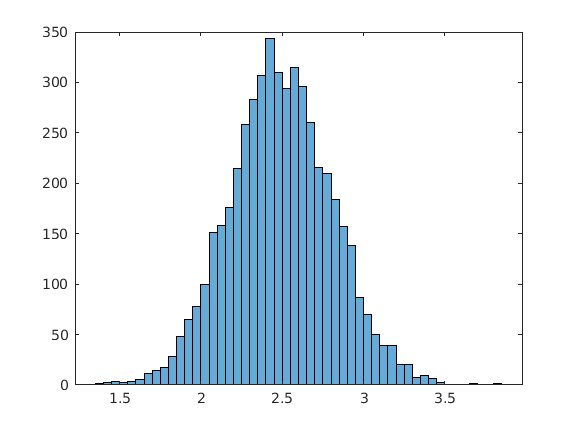


%lets plot distribution at x = 2.5(far from sensor)
% we can see that likehood functions looks like gaussian
x_data = normrnd(2.5,sqrt(0.1),[1,5000]);
histogram(x_data)

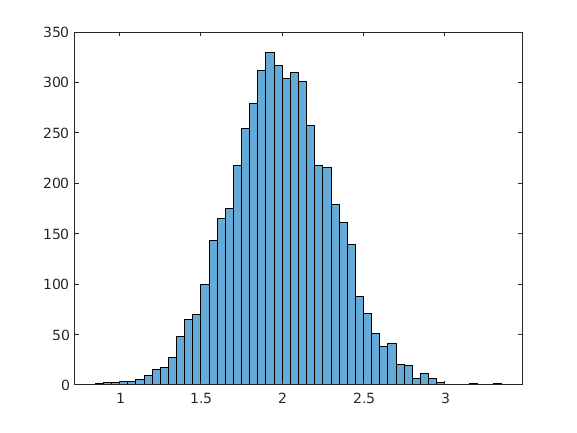

measurement_data = sqrt((0.5-x_data).^2+0.1.^2);
histogram(measurement_data)

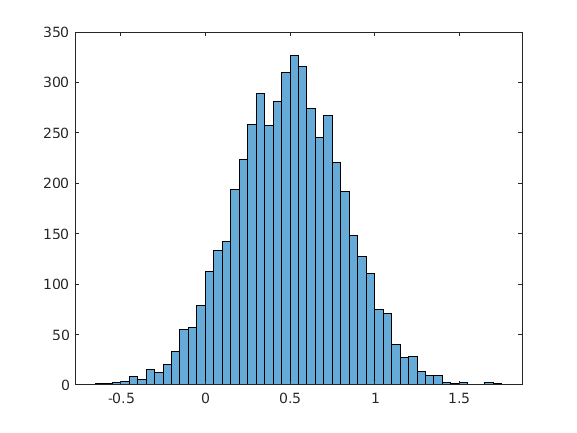


% lets plot distribution at x = 0.5( very close to sensor)
% we can see that likelihood function doesn't really look like gaussian
% I think this is a big reason why filters doesn't behave well at x = 0.5
x_data = normrnd(0.5,sqrt(0.1),[1,5000]);
histogram(x_data)

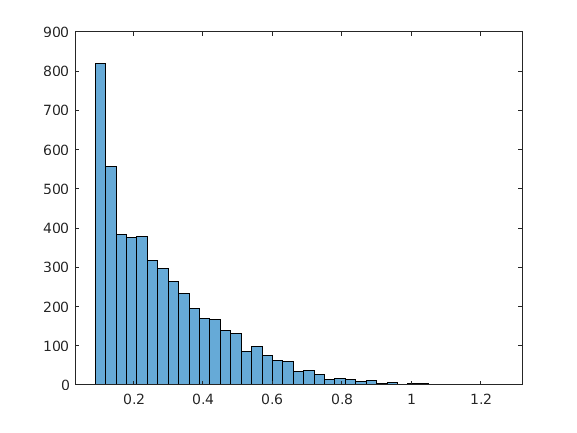

measurement_data = sqrt((0.5-x_data).^2+0.1.^2);
histogram(measurement_data)

Functions

function []= task5(rng_number)

%generate data
rng('default'); rng(rng_number);
DT=0.1; nk=100; Qc=1; r=0.1; x0=[4;0];
T=(1:nk)*DT; X=zeros(1,nk); Y=zeros(1,nk);
Ak=[1,DT;0,1]; Qk=Qc*[DT^3/3,DT^2/2;DT^2/2,DT];
x=x0;
for k=1:nk
    x=mvnrnd(Ak*x,Qk)'; X(k)=x(1);
    Y(k)=norm([0.5-x(1);0.1])+sqrt(r)*randn;
end

%lets filter using EKF and EKF2
m0 = [4;0];
P0 = 0.01*eye(2);
Q = Qk;
R=r;

disp(['rng = ',num2str(rng_number)])

filtername={'EKF','EKF2'};
GA={@GaussApproxEKF,@GaussApproxEKF2};
nf=length(filtername);
M1f=zeros(nf,nk);     M1s = zeros(nf,nk);
Mf=zeros(2,nk); Pf=zeros(2,2,nk);   % save for the smoother
for jf=1:nf
    m=m0; P=P0;
    for k=1:nk   % forward sweep (filter)
        [m,P]=gf_predict(m,P,@WienerProcess_f,Q,GA{jf});
        [m,P]=gf_update(m,P,Y(k),@WienerProcess_h,R,GA{jf});
        M1f(jf,k)=m(1);
        Mf(:,k)=m; Pf(:,:,k)=P;
    end
    rmse=sqrt(mean((X(1,:)-M1f(jf,:)).^2));
    disp(['RMS error for filter ' num2str(jf) ' is ' num2str(rmse)])
    
end


plot(T,Y,'b.', ...
    [0,T],[x0(1),X(1,:)],'r-',...
    [0,T],[m0(1),M1f(1,:)],'k-',...
    [0,T],[m0(1),M1f(2,:)],'b-','linewidth',2,'markersize',20);
xlabel('Time')
ylabel('Measurement','rot',0)
legend('data','true',filtername{1},filtername{2},'location','SW')

end





function [mu,S,C]=GaussApproxEKF(m,P,g,E)    
[mu,Gx]=g(m);
C=P*Gx';
S=Gx*C+E;
end


function [mu,S,C]=GaussApproxEKF2(m,P,g,E)
[mu,Gx,Gxx]=g(m);
C=P*Gx';
S=Gx*C+E;
n=size(E,1);
for i=1:n
    % GXX is a 3-dimensional array in the lecture; here it's a cell array
    mu(i)=mu(i)+0.5*trace(Gxx{i}*P);  
    for j=1:n
        S(i,j)=S(i,j)+0.5*trace(Gxx{i}*P*Gxx{j}*P);
    end
end
end

function [m,P]=gf_update(m,P,y,h,R,GaussApprox)
if ~isnan(y)
    [mu,S,C]=GaussApprox(m,P,h,R);
    K=C/S;
    P=P-K*S*K';
    m=m+K*(y-mu);
end
end

function [m,P]=gf_predict(m,P,f,Q,GaussApprox)
[m,P]=GaussApprox(m,P,f,Q);
end

function [f,Fx,Fxx] = WienerProcess_f(x)
    DT = 0.1;
    f = [x(1) + DT*x(2);x(2)];
    Fx = [[1 DT];[0 1]];
    Fxx{1} = zeros([2,2]);
    Fxx{2} = zeros([2,2]);
end

function [h,Hx,Hxx] = WienerProcess_h(x)
    h = norm([(0.5-x(1)) 0.1]);
    Hx = [-(0.5-x(1))/h 0];
    Hxx{1} = 0.01/(h.^3)*[[1 0];[0 0]];
end

function [f,Fx,Fxx]=pendulum_f_leapfrog(x)
DT=0.01; g=9.81;
A = [1 DT;0 1];
f = A*x - [DT/2; 1]*g*DT*sin(x(1)+DT/2*x(2));
Fx = A - [DT/2,DT^2/4;1,DT/2]*g*DT*cos(x(1)+DT/2*x(2));
Fxx{2} = g*DT*sin(x(1)+DT/2*x(2))*[1,DT/2;DT/2,DT^2/4];
Fxx{1} = Fxx{2}*DT/2;
end

function [f,Fx,Fxx]=pendulum_f(x)
DT=0.01; g=9.81;
f=[x(1) + DT*x(2);x(2)] -[DT/2;1]*DT*g*sin(x(1) + DT/2*x(2));

Fx_1 = [[1 DT];[0 1]];
Fx_2 = [[DT/2 1/4*DT^2];[1 DT/2]]*DT*g*cos(x(1) + DT/2*x(2));
Fx = Fx_1-Fx_2;

Fxx{1}=[[1/2*DT^2 1/4*DT^3];[1/4*DT^3 1/8*DT^4]]*g*sin(x(1) + DT/2*x(2));
Fxx{2}=[[DT 1/2*DT^2];[1/2*DT^2 1/4*DT^3]]*g*sin(x(1) + DT/2*x(2));
        
end

function [h,Hx,Hxx]=pendulum_h(x)
h=sin(x(1));
Hx=[cos(x(1)) 0];
Hxx{1}=[-sin(x(1))   0
          0          0];
end